# BMMO NXE Toolbox - Inline SDM

In this document, we show how to use the inline SDM model. This is a Matlab simulation of the Inline SDM model that is implemented on the TwinScan, for more details on the model see the EDS ([D000347979](https://tc-eu.asml.com/getpdf.html?D000347979-11))

## Getting started

To be able to accurately simulate the inline SDM model on TwinScan using Matlab, we need to load two additional modules: the CET model and the projection toolbox.

module.include('\\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\releases\CET_model', ...
    '-sameNameControl', 'skip');

Including module: cet_model                                                                        R2021-07-21 (C:\Users\anair\AppData\Roaming\MathWorks\MATLAB\ModulesCache\7A3AEEA4CFEC13D9\R2021_07_21\CET_model)


module.include('\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p', ...
    '-sameNameControl', 'skip');

Dependent module: YATA                                                                             R2017-10-28 (\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p\releases\REL_2127_211001\YATA)
Dependent module: PICA_Tool                                                                        R2020-12-03 (\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p\releases\REL_2127_211001\Projection_tools\zeiss\PICA_Tool)
Dependent module: lens_heating                                                                     R2021-02-18 (\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p\releases\REL_2127_211001\Projection_tools\lens_heating)
Dependent module: ProjectionCommon                                                                 R2020-03-11 (\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p\releases\REL_2127_211001\Projection_tools\common)
Dependent module: pro_data                                                  

## Configuring the Inline SDM Model object

To be able to use the inline SDM model, we must first create a model object. The model object can be created usin a BMMO configuration object. This configuration object contains all the necessary settings for the inline SDM model:

configuration3600D = bl3_3600D_model_configuration

configuration3600D = CetModel:  VERSION_5
HocFilter:  Spline
HocModel:  Default
HocPlayback:  Enabled
HocPoly2Spline:  Disabled
InlineSdmModel:  Default
Lens:  3400_34
LensModel:  Default


There are default configurations defined for all the supported TwinScan versions e.g.:

configuration3350B = bmmo_3350B_model_configuration

configuration3350B = CetModel:  THIRD_ORDER
HocFilter:  None
HocModel:  Default
HocPlayback:  Enabled
HocPoly2Spline:  Disabled
InlineSdmModel:  Default
Lens:  3400_34
LensModel:  Default


configuration3400C = bmmo_3400C_model_configuration

configuration3400C = CetModel:  FIFTH_ORDER
HocFilter:  None
HocModel:  Default
HocPlayback:  Enabled
HocPoly2Spline:  Disabled
InlineSdmModel:  Default
Lens:  3400_34
LensModel:  Default


You can modify parameters in an existing configuration object using name-value pairs :

names  = {'CetModel', 'HocPoly2Spline'};
values = {'VERSION_3', 'Enabled'};
configuration3400C.setValue(names, values);
disp(configuration3400C);

CetModel:  VERSION_3
HocFilter:  None
HocModel:  Default
HocPlayback:  Enabled
HocPoly2Spline:  Enabled
InlineSdmModel:  Default
Lens:  3400_34
LensModel:  Default



To list the possible options for each parameter, find the corresponding parameter class:

help bmmo_ConfigurationParameterCetModel

  bmmo_ConfigurationParameterCetModel Configures CET model setting
  This parameter configures the CET model version used during actuation
  simulation. 
  Possible Values: THIRD_ORDER, FIFTH_ORDER, VERSION_3, VERSION_5. 
  This class should not be called directly, but used by
  defining a bmmo_Configuration object.
  See also: bmmo_Configuration, bmmo_3400B_model_configuration, 
  bmmo_3400C_model_configuration, bmmo_3600D_model_configuration

    Reference page for bmmo_ConfigurationParameterCetModel



An inline SDM Model with the proper configuration can be directly created from the configuration object:

inlineSdmModel = configuration3600D.getConfigurationObject('InlineSdmModel')

inlineSdmModel =   bmmo_InlineSdmModelDefault with properties:

          mlDistoIn: [1×1 struct]
          mlWaferIn: [1×1 struct]
        mlChuckCorr: []
    mlWaferResidual: []
             report: []
          lensModel: [1×1 bmmo_LensModelDefault]
           hocModel: [1×1 bmmo_HocModelDefault]


## Using the inline SDM model - reporting

The minimum input needed to run the inline SDM model is an sbc ffp in ml format. In the page [link to separate sheet] we discussed the different ways of obtaining an sbc structure. Once you have an sbc structure, the required ml structure can be created:

*Note that the sbc ffp is always defined on XPA field coordinates, and thus mlDistoIn also requires XPA coordinates.*

In this example, we will directly generate an ffp ìn ml format with random content and set it as input to the model:

mlDisto = testHocModelDefault.generateRandomMlDisto();
inlineSdmModel.mlDistoIn = mlDisto;

With the input ffp set, the inline SDM report can be calculated:

inlineSdmModel.calcReport();

The inline SDM report is a structure that contains corrections, residuals & KPIs:

disp(inlineSdmModel.report);

    lens: [1×1 struct]
     hoc: [1×1 struct]
     res: [1×1 struct]
     cor: [1×1 struct]
     Kpi: [1×1 struct]



Most of the content in the report is also generated on the TwinScan and reported in the ADELsbcOverlayDriftControlNxerep(Protected). Some examples of the content are: 

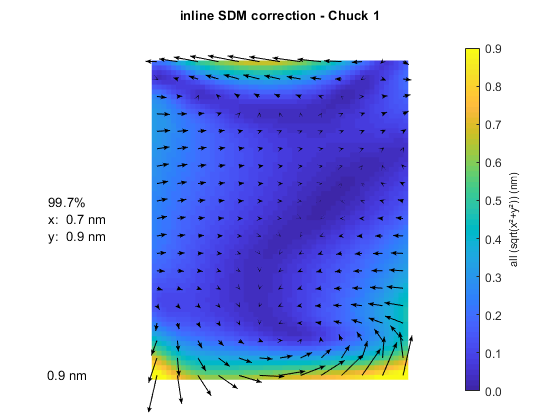

ovl_plot(inlineSdmModel.report.cor, 'scale', 0, 'pcolor', 'field', 'wafer', 1, 'title', 'inline SDM correction - Chuck 1'); 

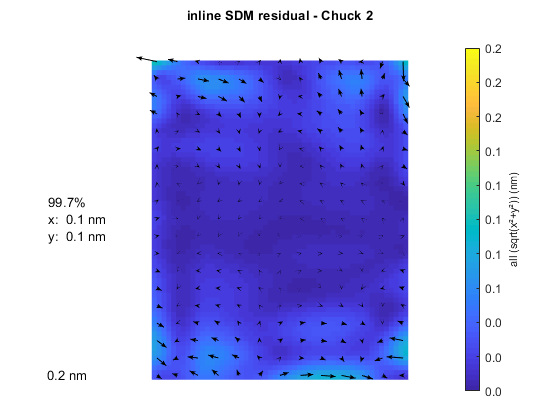

figure; 
ovl_plot(inlineSdmModel.report.res, 'scale', 0, 'pcolor', 'field', 'wafer', 2, 'title', 'inline SDM residual - Chuck 2');

Lens correction KPIs:

disp(inlineSdmModel.report.lens.Kpi)

     maxLensRes: [1×1 struct]
    maxLensCorr: [1×1 struct]
           z2_2: 0.0070
           z3_2: 0.0105



## Using the inline SDM model - actuation

Due to how CET actuation works, the actuation of the ffp at the edge can be slightly different from center fields. Therefore the inline SDM model calculates the actuation seperately from the reporting.  To this end the model accetps an mlWaferIn as an input. If no mlWaferIn is specified, it will default a BMMO layout with 0 overlay. In this case we calculate the actuation and plot the resulting correction per chuck:

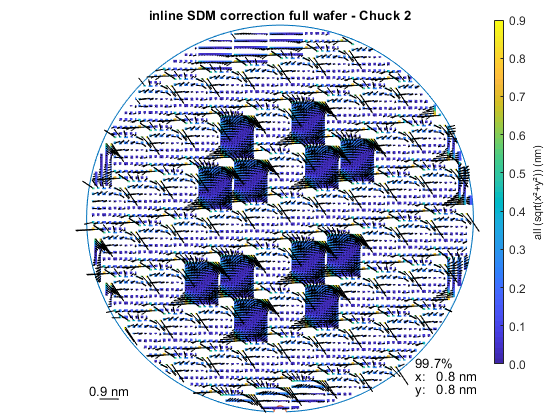

inlineSdmModel.calcActuation;
ovl_plot(inlineSdmModel.mlChuckCorr, 'scale', 0, 'pcolor', 'wafer', 2, 'title', ['inline SDM correction full wafer', ...
    ' - Chuck 2']);

Comparing an inner field to an edge field we can see the previously The mentioned delta:

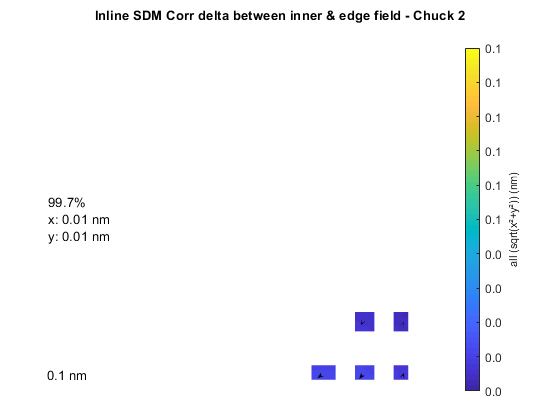

ml_edge_field         = ovl_get_fields(inlineSdmModel.mlChuckCorr, 1);
ml_inner_field_1      = ovl_get_fields(inlineSdmModel.mlChuckCorr, 25);
ml_delta_edge_inner   = ovl_sub(ovl_average_fields(ml_edge_field), ovl_average_fields(ml_inner_field_1));
ovl_plot(ml_delta_edge_inner, 'scale', 0, 'pcolor', 'field', 'wafer', 2, 'title', ...
    'Inline SDM Corr delta between inner & edge field - Chuck 2', 'prc', 2);

This delta does not exist when comparing two inner fields:

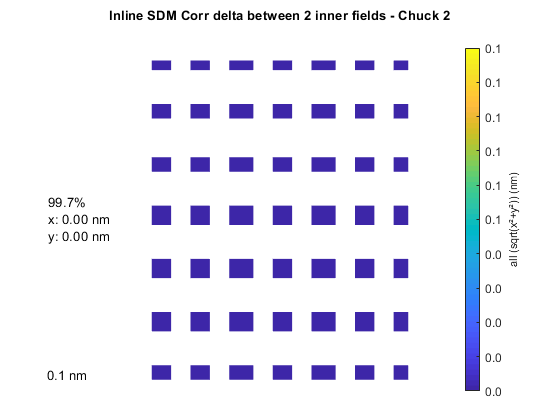

ml_inner_field_2      = ovl_get_fields(inlineSdmModel.mlChuckCorr, 35);
ml_delta_inner_fields = ovl_sub(ovl_average_fields(ml_inner_field_1), ovl_average_fields(ml_inner_field_2));
ovl_plot(ml_delta_inner_fields, 'scale', 0, 'pcolor', 'field', 'wafer', 2, 'title', ...
    'Inline SDM Corr delta between 2 inner fields - Chuck 2', 'prc', 2);

The model also calculates the residual of the mlWaferIn input after applying the inline SDM correction. In the following example we set the same default zero BMMO layout explicitly to mlWaferIn, and calculate the correction again:

ml_dummy = bmmo_process_input(bmmo_default_input);
inlineSdmModel.mlWaferIn = ovl_get_wafers(ml_dummy, 1:2);
inlineSdmModel.calcActuation;

When calculating the residual, the assumption is made that the wafers in mlWaferIn were exposed in alternating chuck order, starting on chuck 1. 

%%TO DO: Show how to change the chuck ID -> check with ANBZ

## Using the inline SDM model - advanced diagnostics

The inline SDM model consists of 2 submodels, the lens model and the HOC model. These models can be used separately in a similar way as the inline SDM model. They can be created directly from the configuration object. Use the help command to get more details on the inputs, outputs & methods:

hocModel = configuration3400C.getConfigurationObject('HocModel');
help hocModel

--- help for bmmo_HocModelDefault ---

  bmmo_HocModelDefault BMMO & BL3 NXE HOC model.
 
  This class calculates the KPIs correction & residuals for the HOC
  part of the inline SDM model. For details on the model see the
  EDS (D000347979)
 
  bmmo_HocModelDefault Properties:
    mlDistoIn             - SBC ffp in ml format
    mlWaferIn             - Wafers to applly HOC correction on
    chuckId               - Chuck Id of wafers in mlWaferIn
    actuationOutput       - Structure containing correction and residual
    report                - Structure with reporitng KPIs & residuals
    <a href="matlab:help bmmo_HocModelDefault/mlHocInput">mlHocInput<

For advanced diagnostics, the lens model can be run using the Lens FingerPrint (LFP). The LFP is not available from a BMMO/BL3 zip, but can be loaded from the mdl file of the corresponding exposure:

lensModel = configuration3400C.getConfigurationObject('LensModel');
lensModel.mlIn = ovl_average(testHocModelDefault.generateRandomMlDisto());

mdlDir  = '\\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\etc\BMMO-NXE\';
mdlPath = [mdlDir 'BMMO.mdl.gz']

mdlPath = '\\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\etc\BMMO-NXE\BMMO.mdl.gz'

lensModel.readLfpFromMdl(mdlPath);

If the LFP is used in the lens model, make sure to set the time filter weighting factor to the correct value when simulating a control job:

lensModel.timeFilterCoeff = 0.4;

Running the lens model produces a lens correction and KPI report: 

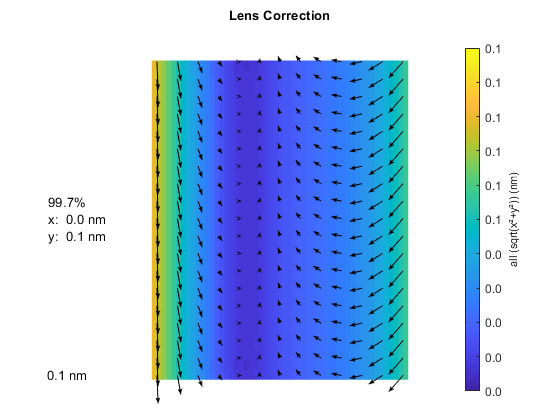

lensModel.run()
ovl_plot(lensModel.mlOut, 'scale', 0, 'pcolor', 'field', 'title', 'Lens Correction');

disp(lensModel.report)

         adjPob: [47×1 double]
    staticCorrZ: [1×1 struct]
            par: [1×1 struct]



An inlineSDM model object can also be constructed from the class constructor, the class constructor takes a configuration object as a required input, and the input ml files as optional inputs::

inlineSdmModel = bmmo_InlineSdmModelDefault(configuration3600D, mlDisto, ml_dummy);

In general it's reccomended to generate a model object directly from a configuration object, as shown before:

Each inline SDM model object contains a HOC model and a Lens model object. Running the full inline SDM simulation using the LFP can thus be done by accessing the Lens Model object directly:

inlineSdmModel.lensModel.readLfpFromMdl(mdlPath);
inlineSdmModel.run();